clear 
clc

Ex1.1

dt=10^-7; %time step
R=10; %Ohm
C=1*10^-6; %milifarad
L=4*10^-6; %millihenry
out=sim('sim1.slx');

Ex1.2

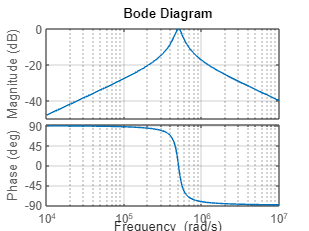

omega = 2 * pi * logspace(-3,3,173);
num=[1 0];
den=[(C*R) 1 (R/L)];
SYS=tf(num,den);
bode(SYS), grid

imp_sys=impulse(SYS);
fft_sys=fft(imp_sys);
N=length(fft_sys);
% f = 2*pi*1/dt*(0:(N-1))/N;
% mag_sys=abs(fft_sys);
% phase_deg=rad2deg(angle(fft_sys));

% fh = figure;
% ah = subplot(2,1,1,'Parent',fh);
% bh = subplot(2,1,2,'Parent',fh);
% semilogx(ah,f,20*log10(mag_sys))
% semilogx(bh,f,phase_deg)

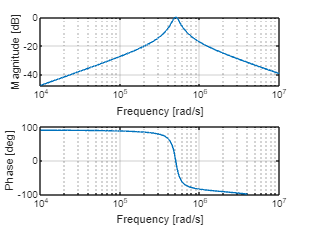

x1=out.x1;
y1=out.x2;
X1=fft(x1);
Y1=fft(y1);
H=Y1./X1;
N=length(H);
f = 2*pi*1/dt*(0:(N-1))/N;
mag_sys=abs(H);
phase_deg=rad2deg(angle(H));

figure()
subplot(2,1,1);
semilogx(f,20*log10(mag_sys)), grid on
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f,phase_deg), grid on
ylim([-100 100])
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')


%calculating damping using 2 methods

%logarithmic damping decrement:

x0 = 5.424*exp(-3);
x1 = 2.885*exp(-3);

epsilon1 = log(x0/x1)/(2*pi) 

epsilon1 = 0.1005


%Half powe method

omega2 = 552354;
omega1 = 452640;
omegar = 500015;

epsilon11 = (omega2 - omega1)/(2*omegar)

epsilon11 = 0.0997

Task 1.3

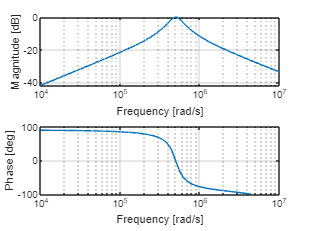

R=5;
out2=sim('sim1.slx');

x2=out2.x1;
y2=out2.x2;
X2=fft(x2);
Y2=fft(y2);
H2=Y2./X2;
N2=length(H2);
f2 = 2*pi*1/dt*(0:(N2-1))/N2;
mag_sys2=abs(H2);
phase_deg2=rad2deg(angle(H2));

figure()
subplot(2,1,1);
semilogx(f2,20*log10(mag_sys2)), grid on
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f2,phase_deg2), grid on
ylim([-100 100])
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')


%logarithmic damping decrement:

x02 = 6.018*exp(-3);
x12 = 1.669*exp(-3);

epsilon2 = log(x02/x12)/(2*pi) 

epsilon2 = 0.2041

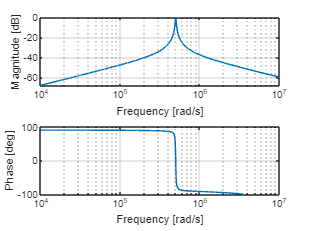

R=100;
out3=sim('sim1.slx');

x3=out3.x1;
y3=out3.x2;
X3=fft(x3);
Y3=fft(y3);
H3=Y3./X3;
N3=length(H3);
f3 = 2*pi*1/dt*(0:(N3-1))/N3;
mag_sys3=abs(H3);
phase_deg3=rad2deg(angle(H3));

figure()
subplot(2,1,1);
semilogx(f3,20*log10(mag_sys3)), grid on
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f3,phase_deg3), grid on
ylim([-100 100])
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')

%logarithmic damping decrement:

x03 = 9.374*exp(-3);
x13 = 8.808*exp(-3);

epsilon3 = log(x03/x13)/(2*pi) 

epsilon3 = 0.0099